# Alireza Amiri - Robotics Assignment 4

## Forward_Kinematics

clear;
clc;

tic
%% Definition
Number_of_Links = 7; 
    
theta = sym('theta', [Number_of_Links 1]); 
assume(theta, 'real');
syms a1 a2 a3 a4 a5 a6 a7;

Lengths = [a1; a2; a3; a4; a5; a6; a7]; % Link lengths

% Define physical properties for each link
Masses = sym('m', [Number_of_Links, 1], 'real'); % Mass of each link

theta = sym('theta', [Number_of_Links, 1]); assume(theta, 'real')
theta_dot = sym('dtheta', [Number_of_Links, 1]); assume(theta_dot, 'real');

% DH parameters (d, alpha, a, theta) for each joint
DH_Params = [
    0, 0, Lengths(1), theta(1);
    0, 0, Lengths(2), theta(2);
    0, 0, Lengths(3), theta(3);
    0, 0, Lengths(4), theta(4);
    0, 0, Lengths(5), theta(5);
    0, 0, Lengths(6), theta(6);
    0, 0, Lengths(7), theta(7);
];

disp('DH Parameter Table:');

DH Parameter Table:


disp(DH_Params);

$$\left(\begin{array}{cccc} 0 & 0 & a_{1} & \theta_{1}\\ 0 & 0 & a_{2} & \theta_{2}\\ 0 & 0 & a_{3} & \theta_{3}\\ 0 & 0 & a_{4} & \theta_{4}\\ 0 & 0 & a_{5} & \theta_{5}\\ 0 & 0 & a_{6} & \theta_{6}\\ 0 & 0 & a_{7} & \theta_{7} \end{array}\right)$$


% Generate the transform matrices based on DH table
T = sym(zeros(4, 4, Number_of_Links));
for i = 1:Number_of_Links
    T(:, :, i) = DH(DH_Params(i, 1), DH_Params(i, 2), ...
                    DH_Params(i, 3), DH_Params(i, 4));
end

% Compute total transformation matrices
T_Total(:, :, 1) = T(:, :, 1);
for i = 2:Number_of_Links
    T_Total(:, :, i) = T_Total(:, :, i-1) * T(:, :, i)
end

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 0\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 0\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1}-\sin\left(\theta_{4}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{1}+\sin\left(\theta_{4}\right)\,\sigma_{3} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{2}=\cos\left(\theta_{4}\right)\,\sigma_{3}-\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 0\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1}-\sin\left(\theta_{4}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{1}+\sin\left(\theta_{4}\right)\,\sigma_{3} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{2}=\cos\left(\theta_{4}\right)\,\sigma_{3}-\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{5}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{5}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{5}\right)\,\sigma_{3}-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{4}\right)\,\sigma_{4}-\sin\left(\theta_{4}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{5}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 0\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1}-\sin\left(\theta_{4}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{1}+\sin\left(\theta_{4}\right)\,\sigma_{3} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{2}=\cos\left(\theta_{4}\right)\,\sigma_{3}-\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{5}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{5}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{5}\right)\,\sigma_{3}-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{4}\right)\,\sigma_{4}-\sin\left(\theta_{4}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{5}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{6}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{6}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}+a_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{6}\right)\,\sigma_{3}-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\sigma_{5}+\sin\left(\theta_{5}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\sigma_{5}+\sin\left(\theta_{5}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{5}\right)\,\sigma_{4}-\sin\left(\theta_{5}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{4}\right)\,\sigma_{6}-\sin\left(\theta_{4}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{4}\right)\,\sigma_{7}+\sin\left(\theta_{4}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{7}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & a_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & 0\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 0\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{2}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1}-\sin\left(\theta_{4}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{1}+\sin\left(\theta_{4}\right)\,\sigma_{3} & \sigma_{2} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{2}=\cos\left(\theta_{4}\right)\,\sigma_{3}-\sin\left(\theta_{4}\right)\,\left(\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{5}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{5}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{5}\right)\,\sigma_{3}-\sin\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{5}\right)\,\left(\cos\left(\theta_{4}\right)\,\sigma_{5}+\sin\left(\theta_{4}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{4}\right)\,\sigma_{4}-\sin\left(\theta_{4}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{5}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{6}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{6}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}+a_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{6}\right)\,\sigma_{3}-\sin\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\sigma_{5}+\sin\left(\theta_{5}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{6}\right)\,\left(\cos\left(\theta_{5}\right)\,\sigma_{5}+\sin\left(\theta_{5}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{5}\right)\,\sigma_{4}-\sin\left(\theta_{5}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{4}\right)\,\sigma_{6}-\sin\left(\theta_{4}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{4}\right)\,\sigma_{7}+\sin\left(\theta_{4}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{7}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{7}\right)\,\sigma_{3} & 0 & 0\\ \sigma_{2}+\sin\left(\theta_{7}\right)\,\sigma_{3} & \sigma_{1} & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{2}+a_{3}+a_{4}+a_{5}+a_{6}+a_{7}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{7}\right)\,\sigma_{3}-\sin\left(\theta_{7}\right)\,\left(\cos\left(\theta_{6}\right)\,\sigma_{5}+\sin\left(\theta_{6}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{7}\right)\,\left(\cos\left(\theta_{6}\right)\,\sigma_{5}+\sin\left(\theta_{6}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{6}\right)\,\sigma_{4}-\sin\left(\theta_{6}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{5}\right)\,\sigma_{6}-\sin\left(\theta_{5}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{5}\right)\,\sigma_{7}+\sin\left(\theta_{5}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\theta_{4}\right)\,\sigma_{8}-\sin\left(\theta_{4}\right)\,\sigma_{9}\\ \sigma_{7}=\cos\left(\theta_{4}\right)\,\sigma_{9}+\sin\left(\theta_{4}\right)\,\sigma_{8}\\ \sigma_{8}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{9}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$


%% Kinematic Analysis - DH - All Points
P_Total_DH(:, :, 1) = sym(zeros(3, 1));
for i = 1:Number_of_Links
    [P_Total_DH(:, :, i+1), R_Total_DH(:, :, i)] = PR_Link(T_Total(:, :, i));
    zi_DH(:, i) = R_Total_DH(:, 3, i);
end
    
disp('End-Effector Position:');

End-Effector Position:


P_End_Effector_DH = simplify(P_Total_DH(:, :, Number_of_Links+1))

$$P\_End\_Effector\_DH = \left(\begin{array}{c} 0\\ 0\\ a_{1}+a_{2}+a_{3}+a_{4}+a_{5}+a_{6}+a_{7} \end{array}\right)$$

disp('End-Effector Rotation Matrix:');

End-Effector Rotation Matrix:


R_End_Effector_DH = R_Total_DH(:, :, Number_of_Links)

$$R\_End\_Effector\_DH = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\sigma_{2}-\sin\left(\theta_{7}\right)\,\sigma_{3} & 0\\ \sigma_{2}+\sin\left(\theta_{7}\right)\,\sigma_{3} & \sigma_{1} & 0\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{7}\right)\,\sigma_{3}-\sin\left(\theta_{7}\right)\,\left(\cos\left(\theta_{6}\right)\,\sigma_{5}+\sin\left(\theta_{6}\right)\,\sigma_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{7}\right)\,\left(\cos\left(\theta_{6}\right)\,\sigma_{5}+\sin\left(\theta_{6}\right)\,\sigma_{4}\right)\\ \sigma_{3}=\cos\left(\theta_{6}\right)\,\sigma_{4}-\sin\left(\theta_{6}\right)\,\sigma_{5}\\ \sigma_{4}=\cos\left(\theta_{5}\right)\,\sigma_{6}-\sin\left(\theta_{5}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{5}\right)\,\sigma_{7}+\sin\left(\theta_{5}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\theta_{4}\right)\,\sigma_{8}-\sin\left(\theta_{4}\right)\,\sigma_{9}\\ \sigma_{7}=\cos\left(\theta_{4}\right)\,\sigma_{9}+\sin\left(\theta_{4}\right)\,\sigma_{8}\\ \sigma_{8}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)-\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)\\ \sigma_{9}=\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right) \end{array}$$

## Linear and Angular Jacobian

%% Jacobian Analysis - DH
% Initialize the linear and angular Jacobians for each link
J_v_i = sym(zeros(3, Number_of_Links, Number_of_Links)); % Linear Jacobian for each link
J_w_i = sym(zeros(3, Number_of_Links, Number_of_Links)); % Angular Jacobian for each link

% Compute the positions of the end-effectors recursively
PE(:,:,Number_of_Links+1) = sym([0; 0; 0]);
for i = Number_of_Links:-1:1
    if i == 1
        PE(:,:,i) = r_DH_Functions(Lengths(i), 0, theta(i)) + PE(:,:,i+1);
    else
        PE(:,:,i) = R_Total_DH(:,:,i-1) * r_DH_Functions(Lengths(i), 0, theta(i)) + PE(:,:,i+1);
    end
end

% Initialize the z-axis directions for the angular Jacobian
zi_DH_Total = [sym([0; 0; 1]), zi_DH(:, 1:Number_of_Links-1)];

%% Compute Linear Jacobian (Jv)
for i = 1:Number_of_Links
    % Initialize temporary storage for the i-th link's linear Jacobian
    Jv_temp = sym(zeros(3, Number_of_Links));
    
    for j = 1:Number_of_Links
        if j <= i
            if j == i
                % For the current link, scale by 1/2 for the center of mass
                Jv_temp(:,j) = simplify((1/2) * Lengths(i) * diff(Skew(zi_DH_Total(:,j)) * PE(:,:,j), Lengths(i)));
            else
                % For previous links, keep full contribution
                Jv_temp(:,j) = simplify(Lengths(j) * diff(Skew(zi_DH_Total(:,j)) * PE(:,:,j), Lengths(j)));
            end
        else
            % For subsequent links, set contributions to zero
            Jv_temp(:,j) = sym(zeros(3,1));
        end
    end

    % Perform reverse cumulative summation (add subsequent columns to previous ones)
    for j = Number_of_Links-1:-1:1
        Jv_temp(:,j) = Jv_temp(:,j) + Jv_temp(:,j+1);
    end

    % Store the result for the i-th link
    J_v_i(:,:,i) = Jv_temp;
end

%% Compute Angular Jacobian (Jw)
for i = 1:Number_of_Links
    % Initialize temporary storage for the i-th link's angular Jacobian
    Jw_temp = sym(zeros(3, Number_of_Links));

    for j = 1:Number_of_Links
        if j <= i
            % For current and previous links, z-axis contributes
            Jw_temp(:,j) = zi_DH_Total(:,j);
        else
            % For subsequent links, angular contribution is zero
            Jw_temp(:,j) = sym(zeros(3,1));
        end
    end

    % Store the result for the i-th link
    J_w_i(:,:,i) = Jw_temp;
end

%% Output Jacobians for inspection
disp('Linear Jacobians (J_v_i):');

Linear Jacobians (J_v_i):


for i = 1:Number_of_Links
    fprintf('J_v_%d:\n', i);
    disp(J_v_i(:,:,i));
end

J_v_1:


$$\left(\begin{array}{ccccccc} -\frac{a_{1}\,\sin\left(\theta_{1}\right)}{2} & 0 & 0 & 0 & 0 & 0 & 0\\ \frac{a_{1}\,\cos\left(\theta_{1}\right)}{2} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_v_2:


$$\left(\begin{array}{ccccccc} -\frac{a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2}-a_{1}\,\sin\left(\theta_{1}\right) & -\frac{a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0 & 0 & 0 & 0\\ \frac{a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2}+a_{1}\,\cos\left(\theta_{1}\right) & \frac{a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)}{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_v_3:


$$\begin{array}{l} \left(\begin{array}{ccccccc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right)-\sigma_{1} & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-\sigma_{1} & -\sigma_{1} & 0 & 0 & 0 & 0\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+\sigma_{2} & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{2} & \sigma_{2} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{2}\\ \sigma_{2}=\frac{a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)}{2} \end{array}$$

J_v_4:


$$\begin{array}{l} \left(\begin{array}{ccccccc} -\sigma_{1}-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right)-\sigma_{3} & -\sigma_{1}-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-\sigma_{3} & -\sigma_{1}-\sigma_{3} & -\sigma_{1} & 0 & 0 & 0\\ \sigma_{2}+a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)+\sigma_{4} & \sigma_{2}+a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sigma_{2} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{2}=\frac{a_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)}{2}\\ \sigma_{3}=a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{4}=a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

J_v_5:


$$\begin{array}{l} \left(\begin{array}{ccccccc} -\sigma_{3}-\sigma_{7}-a_{1}\,\sin\left(\theta_{1}\right)-\sigma_{1}-\sigma_{5} & -\sigma_{3}-\sigma_{7}-\sigma_{1}-\sigma_{5} & -\sigma_{3}-\sigma_{1}-\sigma_{5} & -\sigma_{3}-\sigma_{1} & -\sigma_{1} & 0 & 0\\ \sigma_{4}+\sigma_{8}+a_{1}\,\cos\left(\theta_{1}\right)+\sigma_{2}+\sigma_{6} & \sigma_{4}+\sigma_{8}+\sigma_{2}+\sigma_{6} & \sigma_{4}+\sigma_{2}+\sigma_{6} & \sigma_{4}+\sigma_{2} & \sigma_{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{a_{5}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}+\theta_{5}\right)}{2}\\ \sigma_{2}=\frac{a_{5}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}+\theta_{5}\right)}{2}\\ \sigma_{3}=a_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=a_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{5}=a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{7}=a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{8}=a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

J_v_6:


$$\begin{array}{l} \left(\begin{array}{ccccccc} -\sigma_{9}-\sigma_{3}-\sigma_{7}-a_{1}\,\sin\left(\theta_{1}\right)-\sigma_{1}-\sigma_{5} & -\sigma_{9}-\sigma_{3}-\sigma_{7}-\sigma_{1}-\sigma_{5} & -\sigma_{9}-\sigma_{3}-\sigma_{1}-\sigma_{5} & -\sigma_{9}-\sigma_{3}-\sigma_{1} & -\sigma_{9}-\sigma_{1} & -\sigma_{9} & 0\\ \sigma_{10}+\sigma_{4}+\sigma_{8}+a_{1}\,\cos\left(\theta_{1}\right)+\sigma_{2}+\sigma_{6} & \sigma_{10}+\sigma_{4}+\sigma_{8}+\sigma_{2}+\sigma_{6} & \sigma_{10}+\sigma_{4}+\sigma_{2}+\sigma_{6} & \sigma_{10}+\sigma_{4}+\sigma_{2} & \sigma_{10}+\sigma_{2} & \sigma_{10} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{5}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}+\theta_{5}\right)\\ \sigma_{2}=a_{5}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}+\theta_{5}\right)\\ \sigma_{3}=a_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=a_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{5}=a_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{6}=a_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{7}=a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{8}=a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{9}=\frac{a_{6}\,\sin\left(\sigma_{11}\right)}{2}\\ \sigma_{10}=\frac{a_{6}\,\cos\left(\sigma_{11}\right)}{2}\\ \sigma_{11}=\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}+\theta_{5}+\theta_{6} \end{array}$$

J_v_7:



disp('Angular Jacobians (J_w_i):');

Angular Jacobians (J_w_i):


for i = 1:Number_of_Links
    fprintf('J_w_%d:\n', i);
    disp(J_w_i(:,:,i));
end

J_w_1:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_w_2:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_w_3:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_w_4:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 & 0 & 0 & 0 \end{array}\right)$$

J_w_5:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 & 1 & 0 & 0 \end{array}\right)$$

J_w_6:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 & 1 & 1 & 0 \end{array}\right)$$

J_w_7:


$$\left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

## Moment of Inertia

% Call the function
IG0 = Inertia_Function(Lengths, Masses);

Moments of Inertia (I):
I_1 = 

$$\frac{a_{1}\,{m_{1}}^{2}}{12}$$

I_2 = 

$$\frac{a_{2}\,{m_{2}}^{2}}{12}$$

I_3 = 

$$\frac{a_{3}\,{m_{3}}^{2}}{12}$$

I_4 = 

$$\frac{a_{4}\,{m_{4}}^{2}}{12}$$

I_5 = 

$$\frac{a_{5}\,{m_{5}}^{2}}{12}$$

I_6 = 

$$\frac{a_{6}\,{m_{6}}^{2}}{12}$$

I_7 = 

$$\frac{a_{7}\,{m_{7}}^{2}}{12}$$


disp('Inertia Tensors in the Base Frame:');

Inertia Tensors in the Base Frame:


disp(IG0);

$$\left(\begin{array}{c} \frac{a_{1}\,{m_{1}}^{2}}{12}\\ \frac{a_{2}\,{m_{2}}^{2}}{12}\\ \frac{a_{3}\,{m_{3}}^{2}}{12}\\ \frac{a_{4}\,{m_{4}}^{2}}{12}\\ \frac{a_{5}\,{m_{5}}^{2}}{12}\\ \frac{a_{6}\,{m_{6}}^{2}}{12}\\ \frac{a_{7}\,{m_{7}}^{2}}{12} \end{array}\right)$$

## Mass Matrix

M = Mass_Matrix(J_v_i, J_w_i, IG0, Masses,Number_of_Links);

Mass Matrix (M):


## Gravitational Matrix

syms g
G = GravitationalVector(J_v_i, Masses, g, Number_of_Links)

## Derivative of Mass Matrix

% Define symbolic variables for joint velocities

M_dot=MassMatrixTimeDerivative(M, theta_dot, theta, Number_of_Links);

Time Derivative of the Mass Matrix (M_dot):


## Coriolis Matrix

B = CoriolisForceVector(M, M_dot, theta_dot, theta);

Coriolis Force Vector (B):


## System Kinematics

K = KineticEnergy(M, theta_dot);

Kinetic Energy (K):


## System Dynamic Equations

ddtheta = diff(theta_dot)

$$ddtheta = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Q = B + G + M*(theta_dot)

toc

Elapsed time is 755.675847 seconds.


## Run Time Plot

% Run times array

runTimes =     0.5366    0.9359    2.4816    7.2096   23.7036  120.3171  755.6758


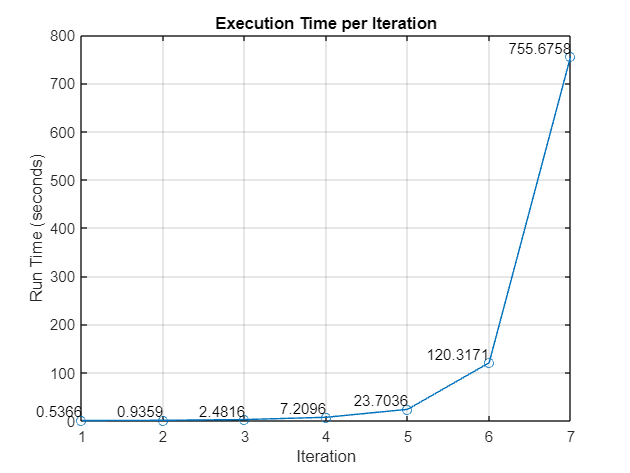

runTimes = [0.5366 0.9359 2.4816 7.2096 23.7036 120.3171 755.6758];

% Create the plot
figure;
plot(1:7, runTimes, '-o');
xlabel('Iteration');
ylabel('Run Time (seconds)');
title('Execution Time per Iteration');
grid on;

% Annotate each point with its value
for i = 1:length(runTimes)
    text(i, runTimes(i), num2str(runTimes(i), '%.4f'), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end